PHYSICS 434

Lab 4: Working with "Real" Data 

Author: Avi Soval 

Partners: Thomas Conaway, Jeff Jiang 

Due: 11.03.19 (Extended to 11.04.19) 

h5disp("gammaray_lab4.h5"); 

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


data = h5read("gammaray_lab4.h5",'/data'); 
data(1,:); 

In the previous lab, we attempted to build a test by which we could omit 'bad data' and keep good data from a simulated dataset for which we actually knew the statistical distribution. In this lab, we now attempt to estimate the background of a sample dataset for which we *do not *know the statistical distribution beforehand. 

Problem I 

In this problem, we consider the data read from a gamma ray satellite in LEO. Every 100 milliseconds, the satellite records the solar phase of the sun in orbit, its [the satellite] longitude with respect to Earth, and the number of particle counts. With 25.92 million rows, each corresponding to 100 milliseconds, there has been data collected for roughly ~2.592 million seconds, which is almost exactly 1 month. A LEO satellite experiences orbital periods of about 90 minutes, meaning that over this one month period it should orbit the Earth roughly 480 times. These initial calculations may be helpful to reference when looking for any periodic changes or behavior in the satellite data. 

We first plot each of the variables - solar phase, Earth longitude, and particle count over the duration of the entire experiment. Since the satellite completes so many orbits over this duration, trying to plot the entire experiment on a single graph will yield in thousands of orbits blocking out the entire plot. As a result, we instead look at smaller time intervals from the entire experiment. The slider below breaks the 30-day experiment into anywhere between 1/2 and 2-day intervals. However, this means that the following plots will show *only *the first interval, i.e the first 1-3 days of data and not anything beyond that. 

time = data(:,1); 
phase = data(:,2); 
longitude = data(:,3); 
counts = data(:,4); 

rows = 25920000; 
interval = 32% break 30-day experiment into this number of intervals 

interval = 32

avg_length = 30/interval; 
disp("Average Interval Length = " + avg_length + " Days"); 

Average Interval Length = 0.9375 Days


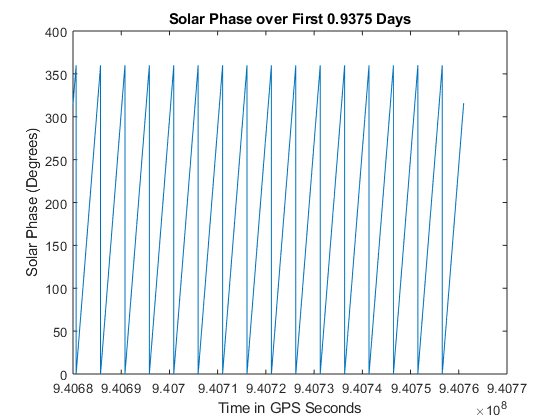

endpoint = fix(rows/interval); 

figure(1)
plot(time(1:endpoint),phase(1:endpoint)); 
xlabel('Time in GPS Seconds'); 
ylabel('Solar Phase (Degrees)'); 
title("Solar Phase over First " + avg_length + " Days");  

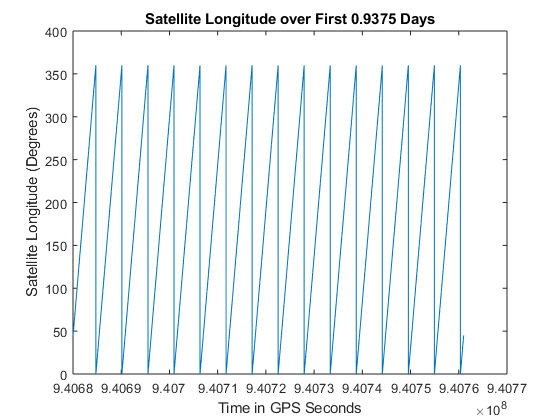


figure(2)
plot(time(1:endpoint),longitude(1:endpoint)); 
xlabel('Time in GPS Seconds'); 
ylabel('Satellite Longitude (Degrees)'); 
title("Satellite Longitude over First " + avg_length + " Days"); 

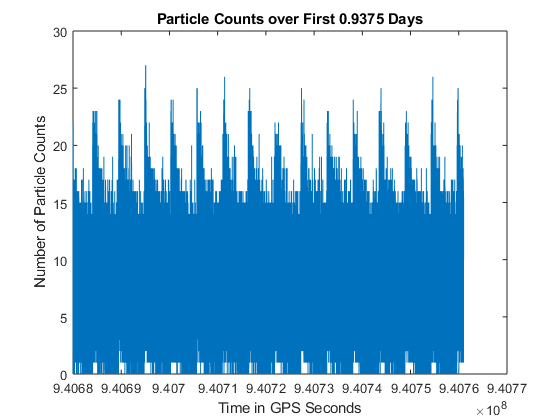


figure(3)
plot(time(1:endpoint),counts(1:endpoint)); 
xlabel('Time in GPS Seconds'); 
ylabel('Number of Particle Counts'); 
title("Particle Counts over First " + avg_length + " Days"); 

As we would expect, the solar phase and Earth longitude plots display almost perfectly periodic behavior, since it is safe to assume that the orbit of the satellite is unchanging. It is difficult to tell from the plots directly if there is any signal contamination in these two graphs, but we could try and compare the maximum amplitudes of each period as well as the length of each period for each interval to try and detect any unexpected fluctuations. Despite this, by looking at our plots, it would still be very reasonable to state that neither the solar phase data or the Earth longitude data have been contaminated. 

For the particle count data, we can see a similar periodic behavior. However, this periodicity is far more variable, primarily in the peak amplitude of each cycle. The peak, corresponding to number of particles counted, is sometimes much higher in certain periods than in others. The width of the particle count data remains considerably more constant from period to period, although the width of the base does seem to spread out or change shape marginally between different cycles. I would expect signal contamination to be more likely here and this could potentially be an explanation for this periodic variation - however, given that the number of particles counted is probably random in time (but not random in orientation during orbit), I would also be inclined to say that much of this variation is just background fluctuation and not necessarily 'contaminated data'. 

We also plot the particle count for a random, sample 90-minute interval to get a close-up view of how this data changes with each orbit. 

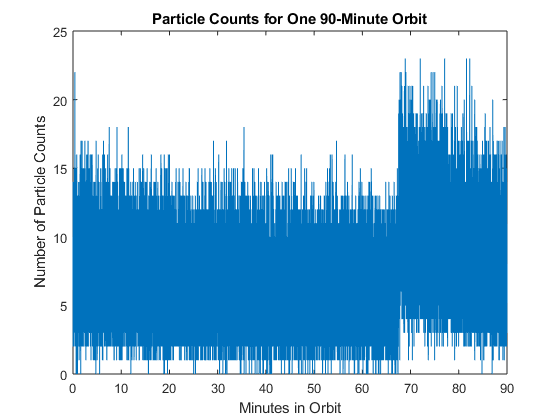

mseconds = 10*60*90; %number of 100-millisecond bins in 90 minutes 

figure(4)
plot((1:mseconds)/600,counts(1:mseconds)); 
xlabel('Minutes in Orbit'); 
ylabel('Number of Particle Counts'); 
title('Particle Counts for One 90-Minute Orbit'); 

In this zoomed view, we get a closer look at the periodic behavior of particle counts for the first 90 minute cycle. Note that even though this plot does not correspond to starting a fresh, new orbit at solar phase 360 degrees, it still displays one entire 90 minute cycle. so we would expect the end of this plot to loop back into something that resembles the beginning of it. The graph seems to loosely resemble an exponential fit, but is cluttered by what looks like significant noise and background fluctuation overlayed over the exponential fit. It seems reasonable to take each period as the standard background for which we want to measure a candidate signal against, as each is the fundamental unit of this larger dataset. Thus, we will try and best fit a distribution and curve to each of these periods, while also looking for any time-dependent variation between them.  

We begin by analyzing again the first full orbit. To improve clarity, I have shifted forward slightly in the data to ensure that the first 90 minute segment corresponds directly to the first full 90 minute orbit by the satellite, as calibrated by the solar phase. By inspection (zooming in until I could pinpoint the first jump), we set this data to start 40,500 entries in, omitting roughly the first 67 minutes of data. However, the impact of this offset is negligible, given that portion of removed data is a fraction of a percent of the whole backgroud data. The Earth longitude at this point is exactly 315 degrees, so we divide the remaining data into periods based on the time interval between successive 315 degree measurements for the longitude. 

ind = find(longitude==315); 

time = time(ind(1):end); 
phase = phase(ind(1):end); 
longitude = longitude(ind(1):end); 
counts = counts(ind(1):end); 

ind2 = find(longitude==315); 

Showing the first period below, correctly starting from the beginning of the signal to the end. 

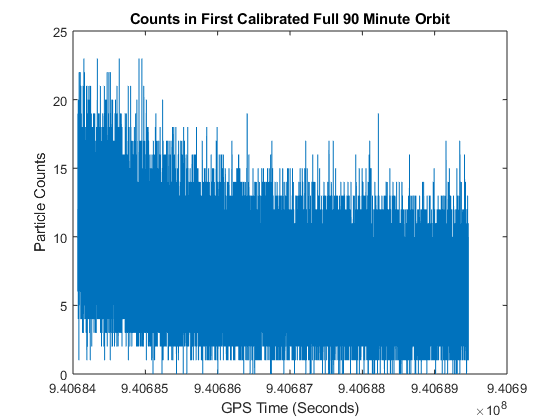

figure(5)

starts = ind2(1); 
ends = ind2(2); 

plot(time(starts:ends),counts(starts:ends)) 
xlabel('GPS Time (Seconds)'); 
ylabel('Particle Counts'); 
title('Counts in First Calibrated Full 90 Minute Orbit'); 

To better see a trendline amongst this data, we can group the time interval into a number of bins and plot average number of particle counts in each. We set the bin size to be 30 seconds. 

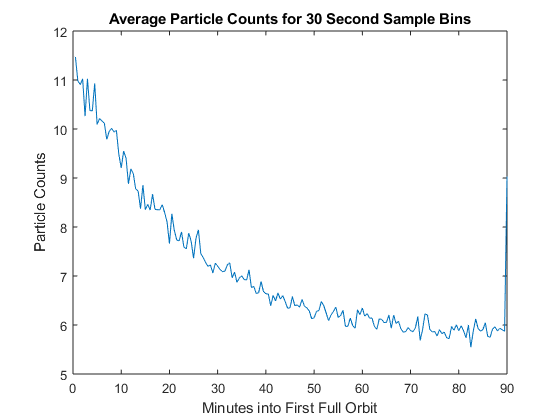

period = ends-starts; 
bin = period/(2*90); 
avgs = zeros(1,180);  
startpoint = 1; 

for i = 1:180
    
    avgs(i) = mean(counts(startpoint:(startpoint+bin))); 
    startpoint = startpoint + bin + 1; 
    
end

figure(6)
plot(((1:180)/2),avgs); 
xlabel('Minutes into First Full Orbit'); 
ylabel('Particle Counts'); 
title('Average Particle Counts for 30 Second Sample Bins'); 

At this point, it looks as if the background data distribution follows either an exponential or Poisson distribution. We can now try and expose any time-dependence *within *a single period. Since we don't know the specific statistical distribution that the data follows, we can look at the average variance within each bin. This will depict whether the data is spreading out or squeezing in over a single cycle - i.e whether flucutations against the background trendline are increasing or decreasing. For the first full orbit, doing so yields the following plot. 

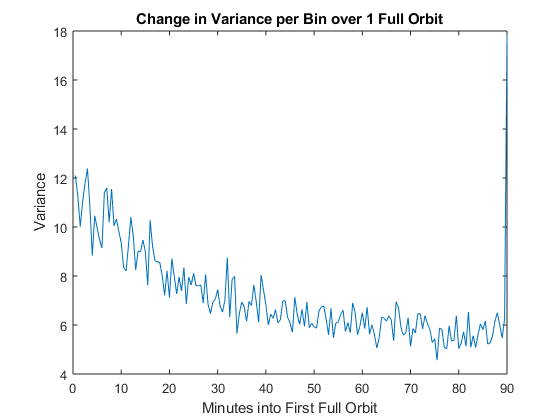

vars = zeros(1,180);
startpoint = 1; 

for i = 1:180
    
    vars(i) = mean(((counts(startpoint:(startpoint+bin))-avgs(i)).^2)); 
    startpoint = startpoint + bin + 1; 
    
end

figure(7)
plot(((1:180)/2),vars); 
xlabel('Minutes into First Full Orbit'); 
ylabel('Variance'); 
title('Change in Variance per Bin over 1 Full Orbit'); 

I believe this plot of the time-dependence of the variance in 1 full orbit offers key insights to the behavior of the background distribution. Evidently, the average variance of each bin (with respect to the average particle counts of each bin) is decreasing over the course of a single orbit. It too seems to follow a roughly exponential distribution in how it decays. This decrease in variance can be explained by the drop in average particle counts - as the average counts drop, any fluctuation measured against it will also have a decreasing variance. This has a few implications for the nature of the background dataset. It means that the background data varies primarily as a function of time within an orbital period, as the amplitude of the background fluctuations decreases with time. It also implies to a degree that there is either a relatively small or nonexistent constant noise term in the background. This is because we would expect an increasing variance with a large *constant *background noise - the difference between each bin average and the random individual fluctuations would jump considerably, therefore increasing the variance of each bin, as the bin count averages dropped with time. The lack of this effect suggests that our background dataset can be characterized primarily by a time-dependent nature, relative to its passage through a single orbit.  

We can now try and develop similar plots, but this time adding another dimension and comparing all the orbits in the dataset. We still use the 30 second bins as before. 

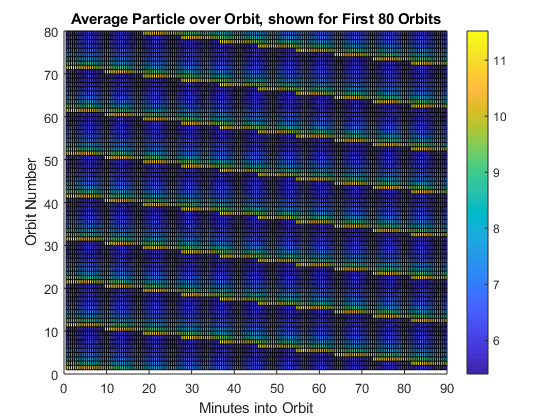

avgs = zeros(80,180); 
vars = zeros(80,180); 
 
start2d = 1; 

for k = 1:80
    
    start1d = 1; 
    
    for i = 1:180
    
        avgs(k,i) = mean(counts(((k-1)*5400 + start1d):((k-1)*5400 + start1d + bin)));
        start1d = start1d + bin; 
    
    end
    
end

[TIME,ORBITNUM] = meshgrid((1:180)/2,1:80); 
figure(8)
surf(TIME,ORBITNUM,avgs)
ylabel('Orbit Number'); 
xlabel('Minutes into Orbit')
colorbar
title('Average Particle over Orbit, shown for First 80 Orbits')
view([0 90]); 

This plot is a 3D surface map collapsed onto a single plane, using a colorbar to indicate the value of the surface instead. On the X-axis, the minutes into the current orbit are plotted, while the Y-axis corresponds to the first 80 out of 480 orbits. What we see are a series of streak-line patterns, offset slightly by the orbit number they correspond to. At first glance, this data would imply that as the orbit number changes, the time interval of each orbit that sees the most particle counts should also shift quite consistently. In other words, this plot suggests that there is a periodically shifting offset in between each orbit. However, this directly contradicts our earlier plots of the phases and particle count data. I believe that what has happened here is that a small offset has been applied to each orbit, shifiting the location of its peak or beginning by roughly 8 or 9 minutes each time. This explains why we see the angled streaks in the above plot, as opposed to completely horizontal bands that we would expect from perfectly perioidic behavior. Thus, we can extrapolate that there is no signifcant variation in the average number of counts from period to period, and we can safely go ahead and average the counts per bin over all orbits. 

We go ahead and produce an average particle count per bin, with the average being taken over all 480 orbits completed by the satellite over the dataset. 

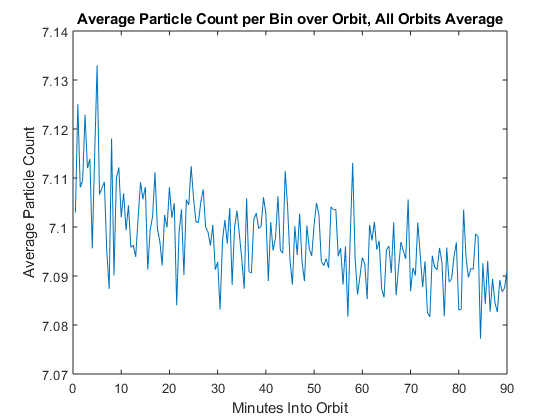

x = 479 * 54000; 
LONGITUDE = longitude(1:x); LONGITUDE = reshape(LONGITUDE,[54000 479]); 
PHASE = phase(1:x); PHASE = reshape(PHASE,[54000 479]); 
TIME = time(1:x); TIME = reshape(TIME,[54000 479]); 
COUNTS = counts(1:x); COUNTS = reshape(COUNTS,[54000 479]); 

COUNTS = mean(COUNTS,2); 
COUNTS = reshape(COUNTS,[180 300]);
COUNTS_avg = mean(COUNTS,2); 

figure(9)
plot(((1:180)/2),COUNTS_avg); 
xlabel('Minutes Into Orbit'); 
ylabel('Average Particle Count'); 
title('Average Particle Count per Bin over Orbit, All Orbits Average');

This is pretty much as far as I got. I kept on running into problems for the rest of my problem 1, and was barely able to make sense enough of problem 2. Thank you for giving me the extension that you did. I've gone ahead and turned in this lab as is and will take the grade for it. 